# Pdf and Cdf of Lognormal RV

Note: this script reproduces the figure of the lognormal RV in Section 2.2.3 of **Statistics for Chemical Engineers**: realizations in regular and logarithmic scale, and pdfs/cdfs. Victor Z UW-Madison, 2020 compare lognormals

clc; clear all; close all hidden;

mu=[0,0,1];
sigma=[sqrt(1/5),sqrt(1),sqrt(1/10)];
w=[0.5,1.5,2.5];
x=linspace(0.001,5,1000);

figure(1)

## Realizations

generate realizations

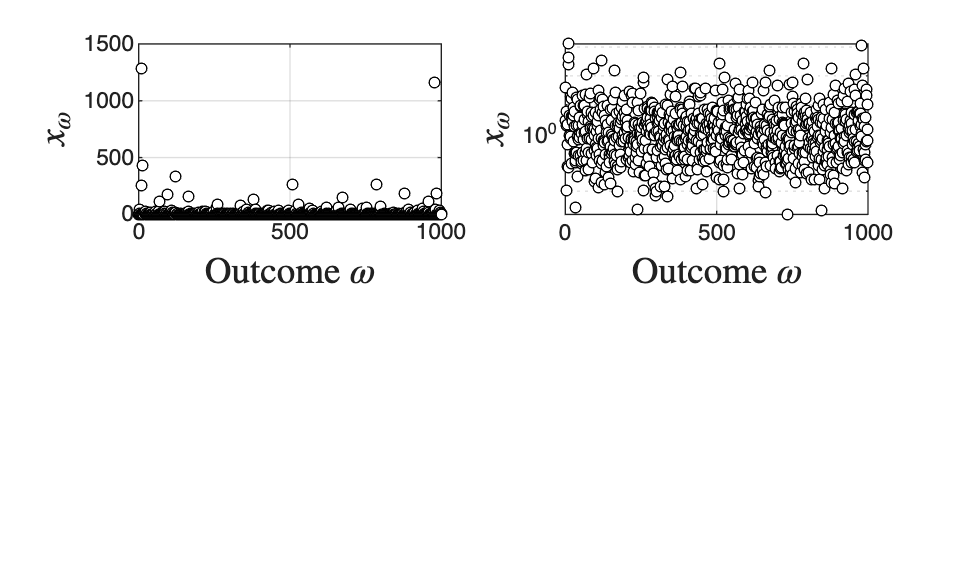

S=1000;
rng(0);
X = lognrnd(0,2,S,1);
figure(1)
subplot(2,2,1)
plot(X,'blacko','MarkerFaceColor','w','MarkerSize',4)
xlabel('Outcome $\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_\omega$','Interpreter','latex','FontSize',14)
grid on
subplot(2,2,2)
semilogy(X,'blacko','MarkerFaceColor','w','MarkerSize',4)
xlabel('Outcome $\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_\omega$','Interpreter','latex','FontSize',14)
grid on

## Pdf

visualize pdf

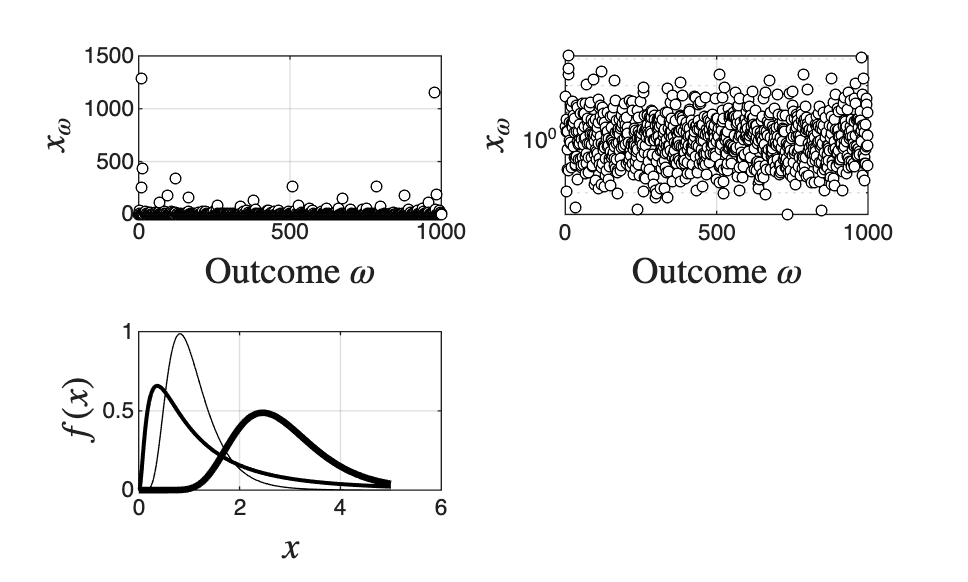

subplot(2,2,3)
for k=1:length(mu)
plot(x,lognpdf(x,mu(k),sigma(k)),'black-','LineWidth',w(k))
hold on
end
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
title('')

## Cdf

visualize cdf

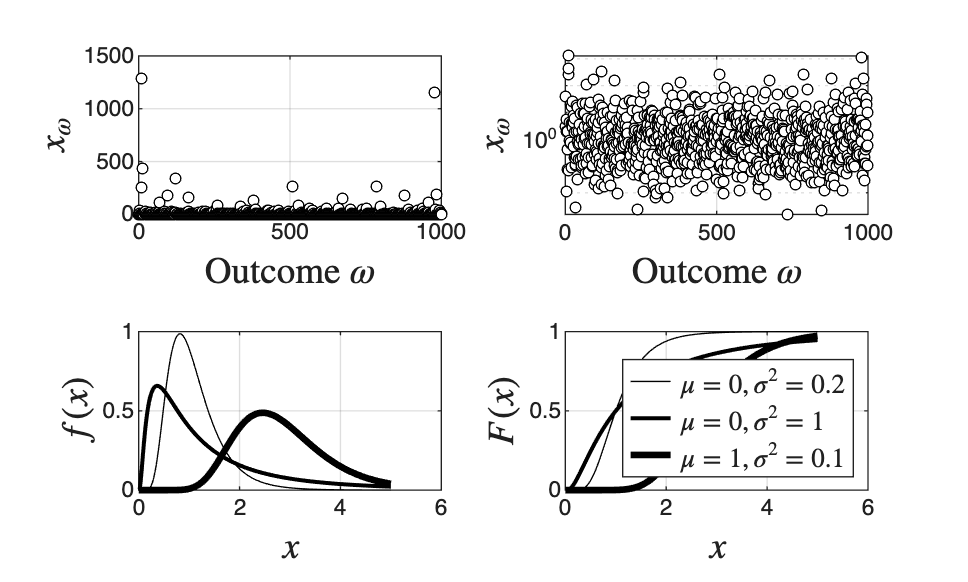

subplot(2,2,4)
for k=1:length(mu)
plot(x,logncdf(x,mu(k),sigma(k)),'black-','LineWidth',w(k))
hold on
end
grid on
lgd=legend('$\mu=0,\sigma^2=0.2$','$\mu=0,\sigma^2=1$',...
'$\mu=1,\sigma^2=0.1$','Interpreter','latex','location','southeast');
lgd.FontSize = 10;
lgd.ItemTokenSize = [15,9];
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
title('')
print -depsc ch2_comparelognormals.eps

## Note

The lognormal RV takes only positive values and is skewed to the right; in logarithmic scale its realizations look Gaussian.